% Задаем ранги критериев
criteria = {'Качество зерна', 'Цена зерна', 'Транспортные расходы', 'Форма оплаты', 'Минимальная партия', 'Надежность поставки'};
ranks = [1, 2, 3, 4, 5, 6];
n = length(criteria);

% Исходная матрица парных сравнений
matrix = [ 1,   2,  2/6, 2/5, 2/3, 2/4;  % Качество зерна
          1/2,  1,  1/6, 1/5, 1/3, 1/4;  % Цена зерна
           6,   6,   1,  6/5, 6/3, 6/4;  % Транспортные расходы
           5,   5,  5/6,  1,  5/3, 5/4;  % Форма оплаты
           3,   3,  3/6, 3/5,  1,  3/4;  % Минимальная партия
           4,   4,  4/6, 4/5, 4/3,  1]; % Надежность поставки

disp("Матрица парных сравнений:");

Матрица парных сравнений:


disp(matrix);

    1.0000    2.0000    0.3333    0.4000    0.6667    0.5000
    0.5000    1.0000    0.1667    0.2000    0.3333    0.2500
    6.0000    6.0000    1.0000    1.2000    2.0000    1.5000
    5.0000    5.0000    0.8333    1.0000    1.6667    1.2500
    3.0000    3.0000    0.5000    0.6000    1.0000    0.7500
    4.0000    4.0000    0.6667    0.8000    1.3333    1.0000




% Вычисление произведений строк
row_products = prod(matrix, 2);%строк
row_n_products = nthroot(row_products, n);%корень
total_sum = sum(row_n_products);

% Нормализация весов
normalized_weights = row_n_products / total_sum;
disp('Нахождение цен альтернатив:');

Нахождение цен альтернатив:


for i = 1:size(row_n_products, 1)
    fprintf('C%d: %.4f\n', i, row_n_products(i));
end

C1: 0.6680
C2: 0.3340
C3: 2.2496
C4: 1.8746
C5: 1.1248
C6: 1.4997



fprintf('\nСумма цен альтернатив: %.4f\n\n', total_sum);


Сумма цен альтернатив: 7.7508




disp('Нахождение весов альтернатив:');

Нахождение весов альтернатив:


for i = 1:length(criteria)
    fprintf('%s: %.4f\n', criteria{i}, normalized_weights(i));
end

Качество зерна: 0.0862
Цена зерна: 0.0431
Транспортные расходы: 0.2902
Форма оплаты: 0.2419
Минимальная партия: 0.1451
Надежность поставки: 0.1935


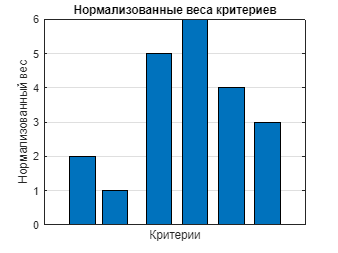


% Построение графика весов критериев
figure;
bar(normalized_weights, ranks); % Использование линий и маркеров
set(gca, 'XTick', 1:length(criteria), 'XTickLabel', criteria); % Установка меток оси X
xlabel('Критерии'); 
ylabel('Нормализованный вес');
title('Нормализованные веса критериев');
grid on;








% Исходные данные
matr = [0.45, 0.2, 0.15, 0.3;
        0.3, 0.3, 0.3, 0.3;
        0.15, 0.35, 0.15, 0.25;
        0.1, 0.15, 0.4, 0.15];

% Матрица рангов
[num_objects, num_experts] = size(matr);
ranks_matrix = zeros(num_objects, num_experts);

% Проходимся по каждому столбцу
for i = 1 : num_experts
    column = matr(:, i);

    % Сортируем оценки по убыванию и сохраняем индексы
    [sorted_scores, sort_idx] = sort(column, 'descend');

    % Создаем массив рангов
    ranks = zeros(num_objects, 1);
    current_rank = 1;
    prev_score = inf;

    for j = 1 : num_objects
        idx = sort_idx(j);
        score = sorted_scores(j);
        
        % Если текущий счет отличается от предыдущего, обновляем ранг
        if score < prev_score
            current_rank = j;
        end

        % Присываиваем ранг
        ranks(idx) = current_rank;

        % Обновление предыдущего счета
        prev_score = score;
    end

    % Если оценки одинаковы
    unique_scores = unique(sorted_scores);
    for k = 1 : length(unique_scores) %цикл по уникальным оценкам
        score = unique_scores(k);
        idxs = find(sorted_scores == score);
        avg_rank = mean(idxs);%выч средний ранг для объектов с одинаковой оценкой
        ranks(sort_idx(idxs)) = round(avg_rank * 10) / 10;
    end

    % Заполнение соответствующего столбца в матрице рангов
    ranks_matrix(:, i) = ranks;
end

for j = 1: num_experts
    column = ranks_matrix(:, j);
    [sorted_column, sort_idx] = sort(column, 'ascend'); %возрастание
    sorted_ranks_matrix(:, j) = sorted_column;
end

% Суммирование рангов по строкам
sum_ranks = sum(sorted_ranks_matrix, 2);

avg_sum_ranks = mean(sum_ranks); %срзначсум

otklon = sum_ranks - avg_sum_ranks;
total_otklon = sum(otklon);

T_i = 0;
unique_ranks = unique(ranks_matrix(:));
for i = 1 : length(unique_ranks)
    rank_group = ranks_matrix(ranks_matrix == unique_ranks(i));
    T_i = T_i + (length(rank_group)) ^ 3;
end

n = num_objects;
m = num_experts;

W = 12 * total_otklon^2 / (n^2 * (m^3 - m) - n * T_i); % Расчет коэффициента конкордации 

fprintf('Исходная матрица оценок:\n');

Исходная матрица оценок:


disp(matr);

    0.4500    0.2000    0.1500    0.3000
    0.3000    0.3000    0.3000    0.3000
    0.1500    0.3500    0.1500    0.2500
    0.1000    0.1500    0.4000    0.1500



fprintf('Матрица рангов:\n');

Матрица рангов:


disp(sorted_ranks_matrix);

    1.0000    1.0000    1.0000    1.5000
    2.0000    2.0000    2.0000    1.5000
    3.0000    3.0000    3.5000    3.0000
    4.0000    4.0000    3.5000    4.0000



fprintf('Сумма по каждой строке в матрице рангов:\n')

Сумма по каждой строке в матрице рангов:


disp(sum_ranks);

    4.5000
    7.5000
   12.5000
   15.5000



fprintf('Среднее арифметическое суммы рангов по всем объектам:\n')

Среднее арифметическое суммы рангов по всем объектам:


disp(avg_sum_ranks);

    10



fprintf('Расчет отклонения суммы рангов по j - объекту оценивания от среднего значения:\n')

Расчет отклонения суммы рангов по j - объекту оценивания от среднего значения:


disp(otklon);

   -5.5000
   -2.5000
    2.5000
    5.5000



fprintf('Total_otklon:');

Total_otklon:

disp(total_otklon);

     0



fprintf('Расчетный показатель T_i:\n')

Расчетный показатель T_i:


disp(T_i);

   124



fprintf('Коэффициент конкордации W:\n')

Коэффициент конкордации W:


disp(W);

     0



if W >= 0.755
    consensus_level = 'Достаточная';
else
    consensus_level = 'Недостаточная';
end

fprintf('Уровень согласованности мнений экспертов: %s\n', consensus_level);

Уровень согласованности мнений экспертов: Недостаточная
